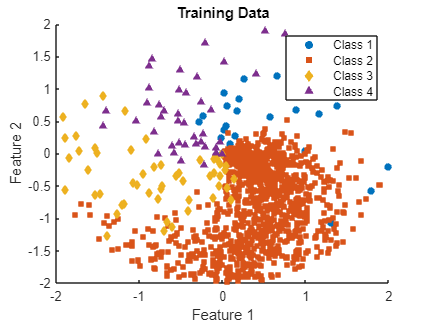

data_train = load('./spiral-5-1tra.dat');
X_train = data_train(:, 1:2);  % 取前兩列作為 x, y 座標
labels_train = data_train(:, end); % 取最後一列作為類別標籤

data_test = load('./spiral-5-1tst.dat');
X_test = data_test(:, 1:2);
labels_test = data_test(:, end);

colors = lines(numel(unique(labels_train))); % 生成顏色陣列
markers = {'o', 's', 'd', '^', 'v', 'p', 'h', 'x', '+'}; % 不同形狀

figure;
hold on;
for i = unique(labels_train)'
    idx = labels_train == i;  % 找到屬於該類別的點
    scatter(X_train(idx, 1), X_train(idx, 2), 30, colors(i, :), markers{i}, 'filled');
end
title('Training Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend(arrayfun(@(x) sprintf('Class %d', x), unique(labels_train), 'UniformOutput', false));

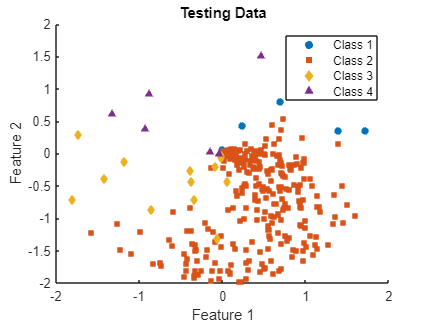


% 畫測試集
figure;
hold on;
for i = unique(labels_test)'
    idx = labels_test == i;
    scatter(X_test(idx, 1), X_test(idx, 2), 30, colors(i, :), markers{i}, 'filled'); % 用不同形狀
end
title('Testing Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend(arrayfun(@(x) sprintf('Class %d', x), unique(labels_test), 'UniformOutput', false));

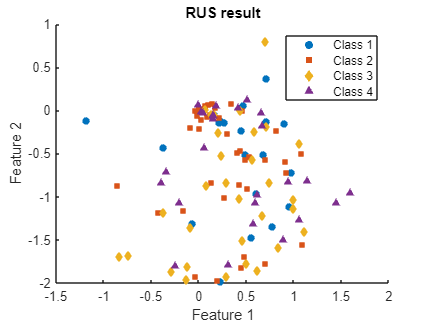

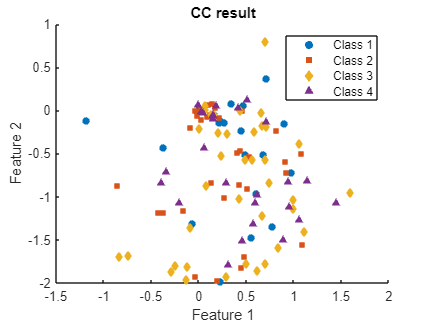

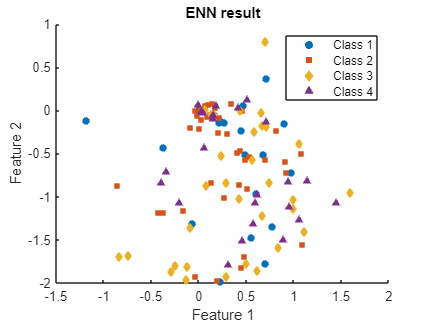

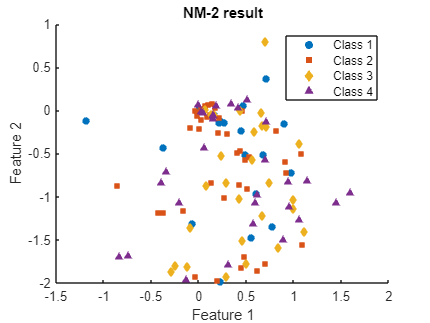

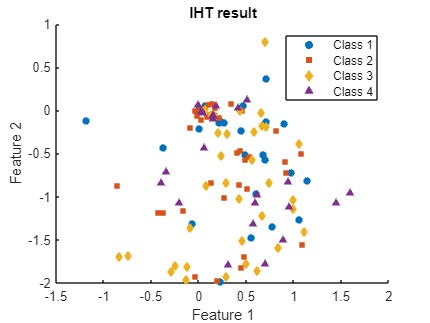

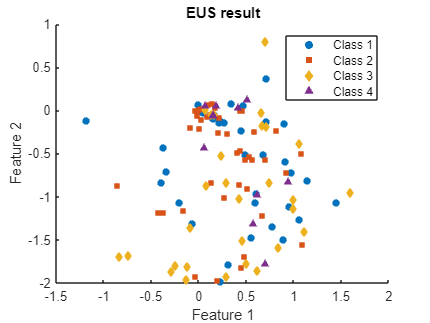

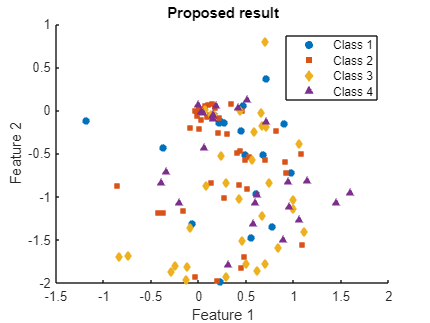


methods = {'RUS', 'CC', 'ENN', 'NM-2', 'IHT', 'EUS', 'Proposed'};
labels_rus = [2 2 4 1 2 2 1 4 1 3 2 2 3 1 4 2 1 2 2 2 2 3 4 4 3 3 1 2 4 3 4 3 1 2 2 3 2 4 3 2 3 1 3 4 1 2 4 2 1 1 2 3 3 4 4 3 2 2 2 2 1 2 3 4 4 4 4 3 1 4 4 1 3 3 3 4 3 2 1 3 4 4 2 3 1 1 2 2 3 2 3 4 1 2 2 3 2 1 3 1 2 2 4 3 1 3 2 1 2 1 2 3 4 3 4 3 2 2 4 2];
labels_cc  = [2 2 3 1 2 2 4 3 1 3 1 2 3 4 4 2 1 2 2 3 3 3 4 4 3 3 1 1 4 4 4 3 1 2 2 3 2 4 3 2 3 1 3 4 1 2 4 2 1 4 3 3 2 4 4 3 2 2 2 2 1 2 3 4 4 4 4 4 1 4 4 1 3 3 3 4 3 2 1 3 3 4 2 3 1 1 2 2 3 2 3 4 1 3 2 3 2 1 3 1 3 2 4 3 1 3 2 1 2 1 2 3 3 3 4 3 3 2 4 2];
labels_enn = [2 2 3 1 2 2 1 3 1 3 2 2 3 4 4 2 1 2 2 2 2 3 4 4 3 3 1 1 4 4 4 3 1 2 2 3 2 4 2 2 3 1 3 4 1 2 4 2 1 4 2 3 2 4 4 3 2 2 2 2 1 2 3 4 4 4 4 3 1 4 4 1 3 3 3 4 3 2 1 3 3 4 2 3 1 1 2 2 3 2 3 4 1 1 2 3 2 1 3 1 2 2 4 3 1 3 2 1 2 1 2 3 3 3 4 3 2 2 4 2];
labels_nm  = [2 2 3 1 2 2 1 4 1 3 4 2 3 4 4 2 1 2 2 2 4 3 4 4 3 3 1 1 4 3 4 3 1 2 2 3 2 4 2 2 3 1 3 4 1 2 4 2 1 4 2 3 2 4 4 3 2 2 2 2 1 2 3 4 4 4 4 3 1 4 4 1 3 4 3 4 3 2 1 3 3 4 2 3 1 1 2 2 4 2 2 4 4 2 2 3 2 1 3 1 2 2 4 4 1 3 2 1 2 1 2 3 3 3 4 3 2 2 4 2];
labels_iht = [2 2 3 1 2 2 1 4 1 3 2 2 3 1 4 2 1 2 2 1 1 3 4 4 3 3 1 1 4 3 4 3 1 2 2 3 2 4 3 2 3 1 3 1 1 2 4 2 1 4 2 3 2 4 4 3 2 2 2 2 1 2 3 1 4 4 4 3 1 4 4 1 3 3 3 4 3 2 1 3 3 4 2 3 1 1 2 2 3 2 3 4 2 4 2 3 2 1 3 1 1 2 4 3 1 3 2 1 2 1 2 3 3 3 4 3 3 2 4 2];
labels_eus = [2 2 3 1 2 2 4 3 1 2 1 2 3 1 4 2 1 2 2 4 2 3 4 1 3 3 1 2 1 3 1 3 1 2 2 3 2 4 2 2 3 1 3 1 1 2 4 2 1 1 2 2 2 1 1 3 2 2 2 2 1 2 3 1 4 1 1 3 1 1 1 1 2 3 3 4 3 2 1 3 3 4 2 3 1 1 2 2 3 2 3 1 1 4 1 2 2 1 3 1 2 2 1 3 1 3 2 1 2 1 2 3 3 3 4 3 2 2 4 2];
labels_pro = [2 2 3 1 2 2 1 4 1 3 2 2 3 4 4 2 1 2 2 2 2 3 4 4 3 3 1 2 4 3 4 3 1 2 2 3 2 4 2 2 3 1 3 4 1 2 4 2 1 4 2 3 2 4 4 3 2 2 2 2 1 2 3 4 4 4 4 3 1 4 4 1 3 3 3 4 3 2 1 3 3 4 2 3 1 1 2 2 3 2 3 4 1 3 2 3 2 1 3 1 2 2 4 3 1 3 2 1 2 1 2 3 3 3 4 3 2 2 4 2];
labels_methods = {labels_rus, labels_cc, labels_enn, labels_nm, labels_iht, labels_eus, labels_pro};

for j = 1:numel(methods)
    figure;
    hold on;
    for i = unique(labels_methods{j})
        idx = labels_methods{j} == i;
        scatter(X_test(idx, 1), X_test(idx, 2), 30, colors(i, :), markers{i}, 'filled');
    end
    title([methods{j}, ' result']);
    xlabel('Feature 1');
    ylabel('Feature 2');
    legend(arrayfun(@(x) sprintf('Class %d', x), unique(labels_methods{j}), 'UniformOutput', false));
end